# **ACM 11 Homework 5 Part 2: Classification**

## Introduction

Do Part 1 first. Then do this part.

## Problem 1: Classification via logistic regression

**(1a) **Please load the ''Auto.csv" data set into MATLAB as you did in Part 1. In this case, we will consider the first 8 variables (i.e., columns) in the dataset.

clear; close all
T = readtable("Auto.csv");

**(1b) **In this part of the problem, we are interested not in the exactly MPG value for each car, but in whether the car has a higher-than-median MPG. 

(i) Create a binary variable $y$ that is 1 if MPG for a given car is above the median, and 0 if it is below the median MPG value. If it is exactly the median, you can choose whether it is 1 or 0.

mpg = T.mpg;
mpg_median = median(mpg);
y = mpg > mpg_median;

(ii) We will use the 7 remaining variables in the data set (cylinders, displacement, horsepower, weight, acceleration, year and origin) to predict whether a car has above or below median MPG. Assemble the 7 remaining variables into a data matrix $X$ where each column contains one variable.

X = [T.cylinders, T.displacement, T.horsepower, T.weight, T.acceleration, T.year, T.origin];

(iii) Use the function `GSCATTER` to create a scatter plot of weight vs. horsepower, grouped according to $y$. Include appropriate axes labels and a legend.

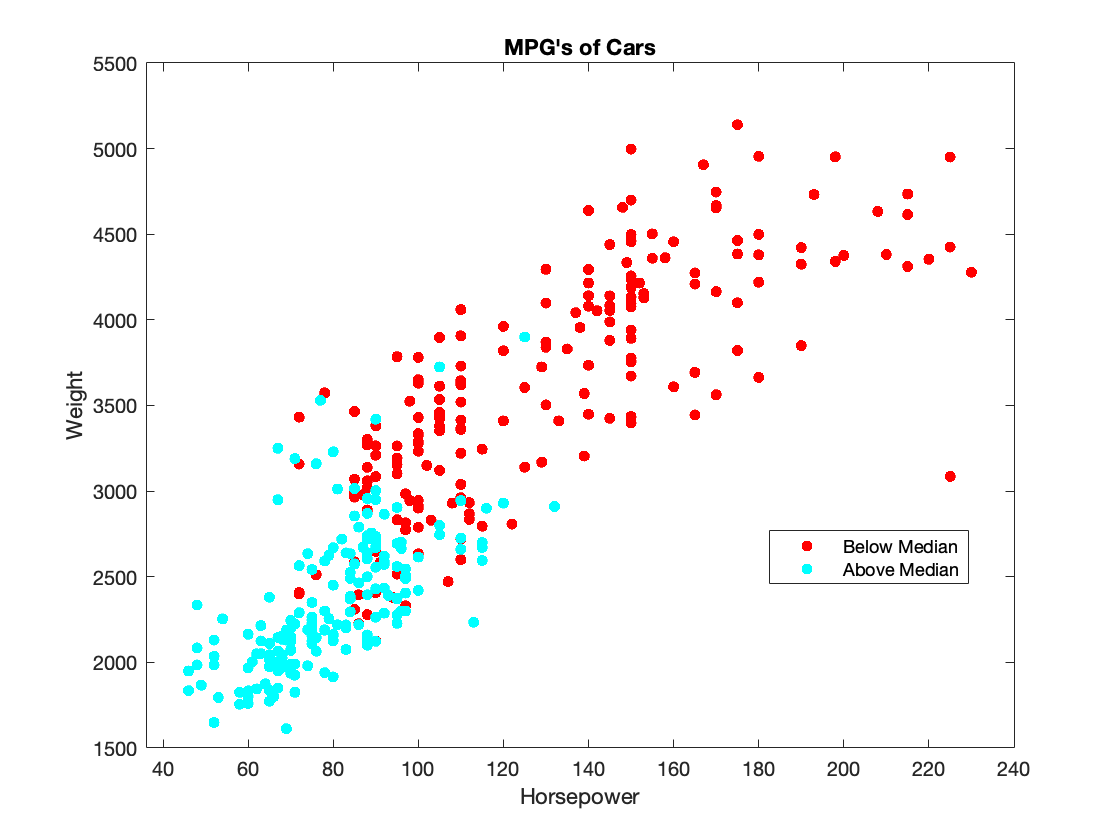

figure;
gscatter(X(:,3), X(:,4), y)
xlabel("Horsepower")
ylabel("Weight")
legend("Below Median", "Above Median")
title("MPG's of Cars")

**(1c) **Split your data into a training and test set. For $n_{\textrm{train}} =300$, use the first $n_{\textrm{train}}$ entries of $y$ and rows of $X$ for training, and save the remaining entries/rows for testing the fitted model. 

n = 300;
y_train = y(1:n);
y_test = y(n+1:end);
X_train = X(1:n, :);
X_test = X(n+1:end, :);

**(1d) **Call the built-in `MNRFIT` function on your training inputs and outputs to fit a classifier. This is a model that will predict the output label for a new input x. Note that the second argument of `MNRFIT` must be a categorical variable. You can convert $y$ into a categorical variable using `categorical(y)`.

classifier = mnrfit(X_train, categorical(y_train));

**(1e) **Use the built-in function MNRVAL to evaluate your classifier on both the training and test sets. MNRVAL will return two values in each row; they are the probabilities that the car with the properties in that row has $y=0$ or $y=1$, respectively. You should set your prediction to be 0 if the first probability is higher than the second, and your prediction to be 1 otherwise. Hint: the syntax `(x>y)` where x and y are vectors of the same shape will return a third vector of the same shape with 1's where x>y and 0's otherwise.

train_eval = mnrval(classifier, X_train);
test_eval = mnrval(classifier, X_test);

train_prediction = train_eval(:, 1) <= train_eval(:, 2);
test_prediction = test_eval(:, 1) <= test_eval(:, 2);

**(1f) **Use `GSCATTER` to plot (i) the training data set horsepower & weight grouped according to whether the classifier prediction is correct or not, and (ii) the same for the test set. Hint: the syntax `x==y` for vectors x and y of the same shape returns a 1 when x = y and a 0 otherwise. Include appropriate axes labels, legends, and title.

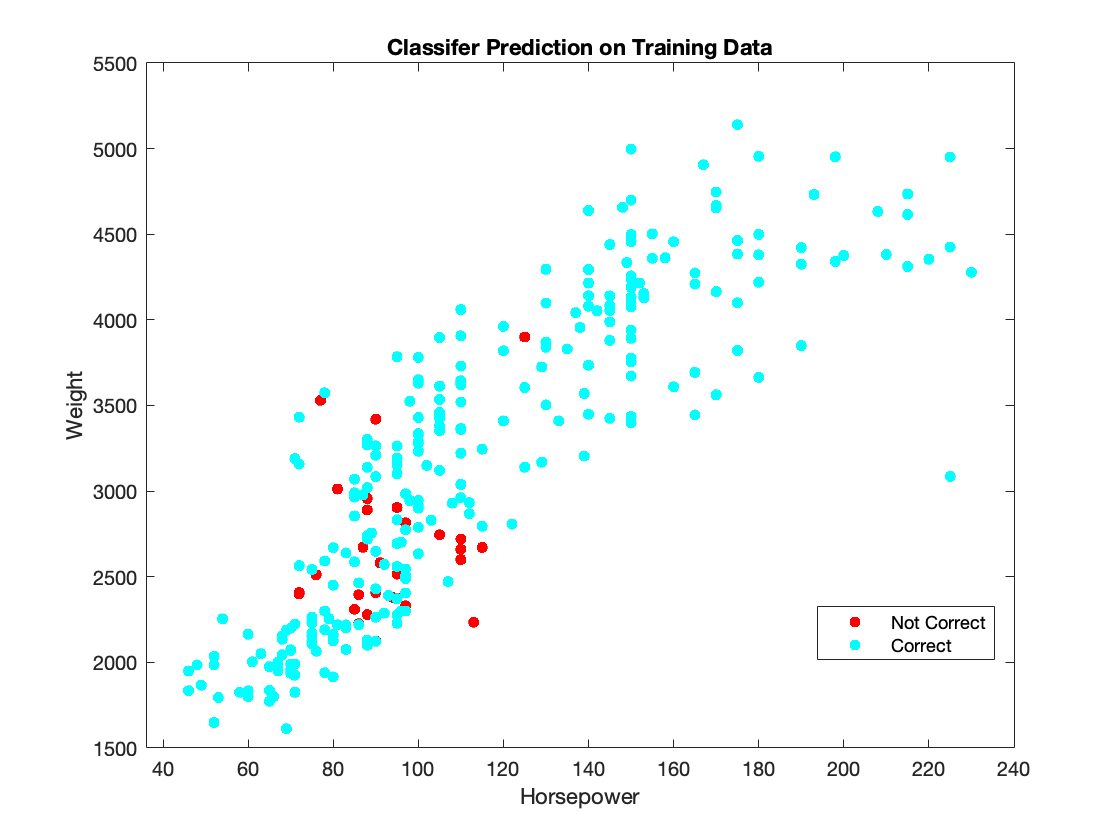

train_accuracy = train_prediction == y_train;
test_accuracy = test_prediction == y_test;

figure;
gscatter(X_train(:, 3), X_train(:, 4), train_accuracy)
xlabel("Horsepower")
ylabel("Weight")
legend("Not Correct", "Correct")
title("Classifer Prediction on Training Data")

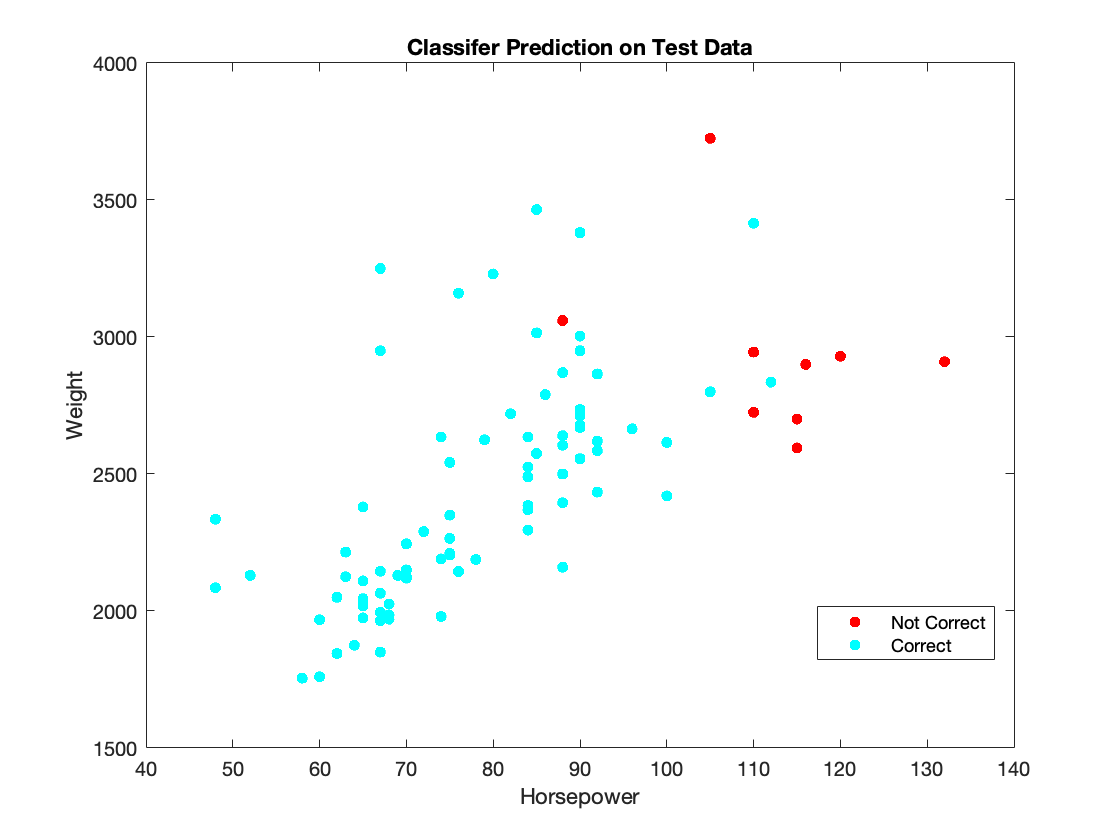


figure;
gscatter(X_test(:, 3), X_test(:, 4), test_accuracy)
xlabel("Horsepower")
ylabel("Weight")
legend("Not Correct", "Correct")
title("Classifer Prediction on Test Data")

**(1g) **What is the misclassification rate for the training set? For the test set? Misclassification rate = # of misclassified cars divided by total number of cars in the set. Please comment below where the misclassified points lie among the data for both the training and test set.

train_rate = (n - sum(train_accuracy)) / n

train_rate = 0.0967

test_rate = (length(test_accuracy) - sum(test_accuracy)) / length(test_accuracy)

test_rate = 0.0978

The misclassified points occur at low horsepower and low weight for the training set and at high horsepower and high weight for the test set. Additionally, for the training set the missclassified points are where the data is more dense while the ones for the test set are usually outliers.

## **Problem 2: Classification via K-Nearest Neighbors**

Now, using the same training/test split as above, use the built-in funcion `FITCKNN` to fit a k-Nearest Neighbor (kNN) classifier. Specify the number of neighbors $k$ when fitting your kNN model, and try $k=1,\ldots, 50$. Check the document for `FITCKNN` to see how to specify this parameter. Train your model on the train set and test it your the test set using the `PREDICT` function. Compute the misclassification rate for both training and test sets. On the same axis, plot the misclassification rate for training and test sets vs $k$. 

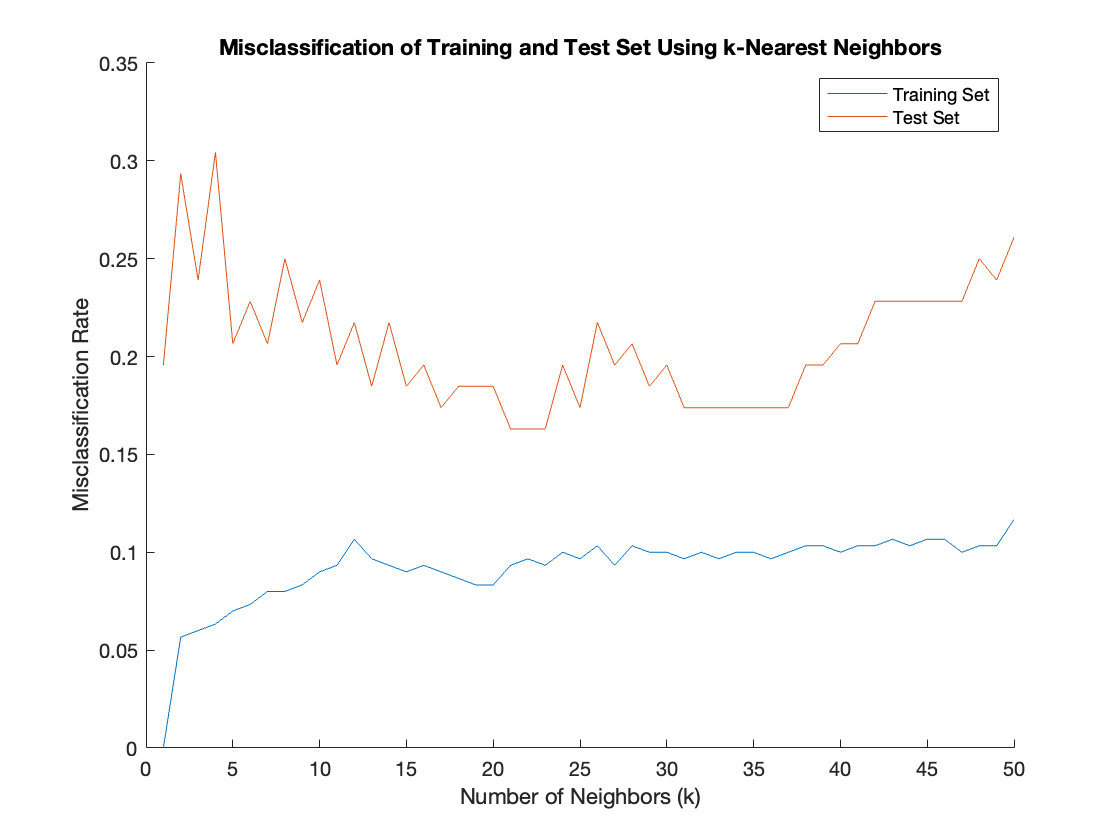

k_max = 50;
misclass_train = zeros(k_max, 1);
misclass_test = zeros(k_max, 1);

for k = 1:k_max
    kNN = fitcknn(X_train, y_train,"NumNeighbors",k);
    train_predict = predict(kNN, X_train);
    test_predict = predict(kNN, X_test);
    
    train_acc = train_predict == y_train;
    test_acc = test_predict == y_test;
    
    misclass_train(k) = (n - sum(train_acc)) / n;
    misclass_test(k) = (length(test_acc) - sum(test_acc)) / length(test_acc);
end

K = linspace(1, k_max, k_max);

figure;
hold on
plot(K, misclass_train)
plot(K, misclass_test)
hold off
xlabel("Number of Neighbors (k)")
ylabel("Misclassification Rate")
legend("Training Set", "Test Set", "Location", "northeast")
title("Misclassification of Training and Test Set Using k-Nearest Neighbors")

Describe the general trends you observe in the training and test misclassification rates as the number of neighbors used to classify increases. For test error, especially, look for the overall large shape of the error function; there will be many small ups and downs that you should "smooth out" in your head. 

For the training set, as the number of neighbors increases the misclassification rate increases and then plateaus when it reaches a rate of about 0.1. For the test set, as the number of neighbors increases the misclassification rate fluctuates a lot at in the beginning, it increases and then decreases again, then it stays low for a while and increases again towards the end. 

How many neighbors leads to the lowest training error? The lowest test error? Explain why these are different.

One neighbor leads to the lowest training error.  Betwee 21 and 23 neighbors leads to the lowest test error. These are different because the for k=1 the fitcknn always has an error of 0 for the training set, but there are not guaranteed values for the test set. A good k value to use for both sets is 20. 